## Proses Input Citra

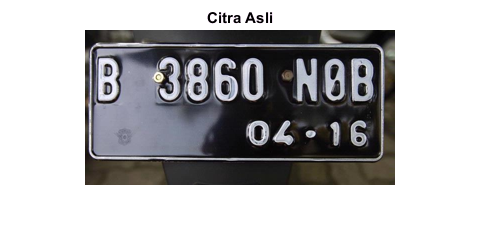

I=imread('2.jpg');
I = imresize(I, 0.5);
figure,
imshow(I);
title('Citra Asli');

## Proses Grayscale

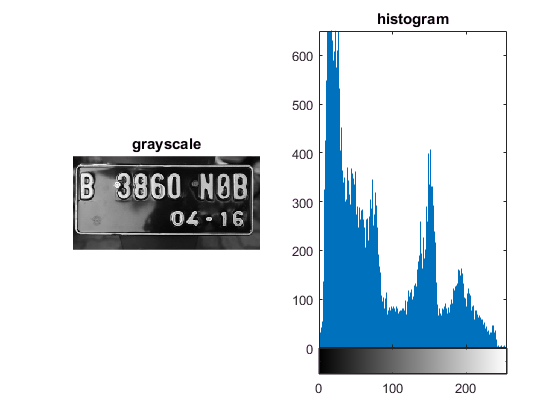

img_gray = rgb2gray(I); 
figure(2),
subplot(1,2,1),
imshow(img_gray); 
title('grayscale');
figure(2),
subplot(1,2,2),
%Menampilkan Histogram
imhist(img_gray);
title('histogram');

## Penambahan Kontras

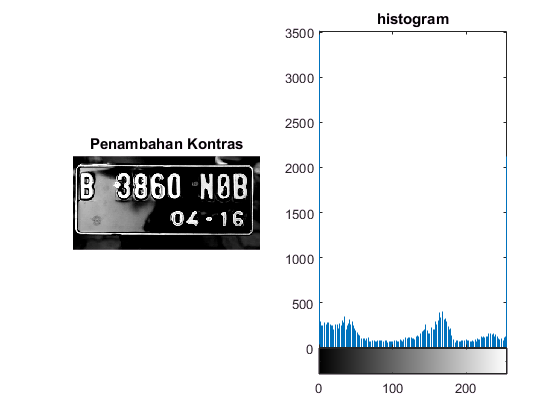

img_gray2 = imadjust(img_gray,[0.2,0.8],[0,1]);
figure(3),
subplot(1,2,1),
imshow(img_gray2);
title('Penambahan Kontras');
figure(3),
subplot(1,2,2),
%Menampilkan Histogram
imhist(img_gray2);
title('histogram');

## Erosi

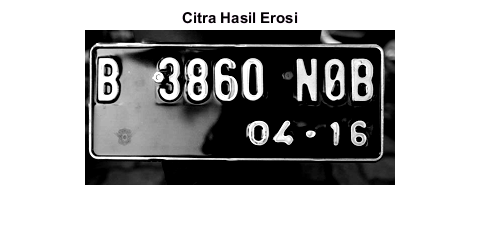

se = [1:1:1];
img_erosi = imerode(img_gray2,se);
figure(5),
imshow(img_erosi);
title('Citra Hasil Erosi');

## Closing (Citra Lebih Halus)

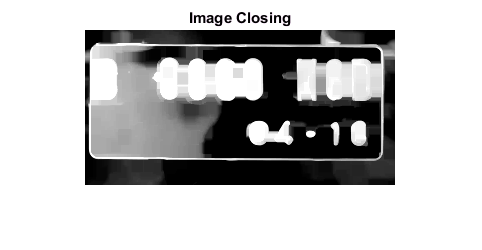

se = strel('rectangle',[10,10]);
img_closing = imclose(img_erosi,se);
figure(6),
imshow(img_closing);
title('Image Closing');

## Pengurangan Noise

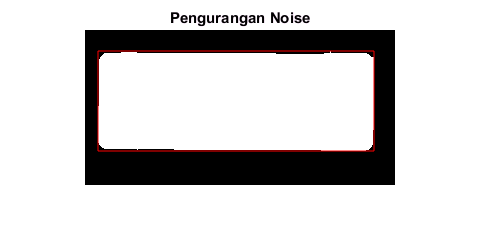

img_lessnoise = double((img_closing)>100);               
img_lessnoise = bwareaopen(img_lessnoise,10);
img_lessnoise = imfill(img_lessnoise,'holes');
se2 = strel('rectangle',[20,20]);
img_lessnoise = imerode(img_lessnoise,se2);
S = regionprops(img_lessnoise,'BoundingBox');
 
figure(7),
imshow(img_lessnoise);
title('Pengurangan Noise');
 
hold on ; %tetap mengaktifan figur citra biner di atas
rectangle('Position', S(1).BoundingBox,'edgecolor','red');

L=bwlabel(img_lessnoise,8);
siz=size(img_lessnoise);
n=max(L(:));
S_i=S.BoundingBox;
idx_x=[S_i(1)-2 S_i(1)+S_i(3)+2];
idx_y=[S_i(2)-2 S_i(2)+S_i(4)+2];
if idx_x(1)<1, idx_x(1)=1; end
if idx_y(1)<1, idx_y(1)=1; end
if idx_x(2)>siz(2), idx_x(2)=siz(2); end
if idx_y(2)>siz(1), idx_y(2)=siz(1); end
% Crop the object and write to ObjCell
im=img_gray2;
hasil=im(idx_y(1):idx_y(2),idx_x(1):idx_x(2));

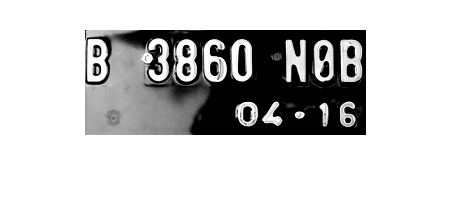


figure,
imshow(hasil);

Clustering

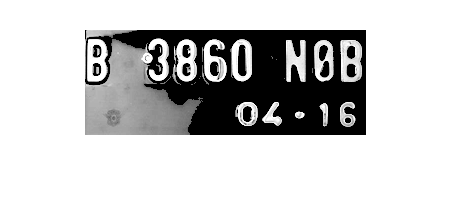

T = graythresh(hasil);
img = hasil;
[idx, centroids]=kmeans(double(img(:)),2,'distance','sqeuclidean','Replicates',5);

segmented_images = cell(1,2);
for k = 1:2
    color = zeros(size(img));
    color(idx==k) = img(idx==k);
    segmented_images{k} = color;
end

figure(),imshow(segmented_images{1},[]);

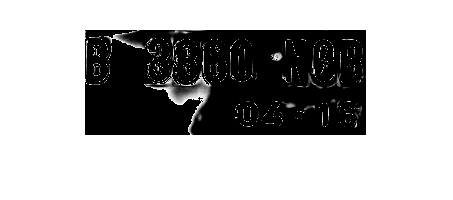

figure(),imshow(segmented_images{2},[]);

rata_cluster = mean(centroids,2);
[tmp, idx] = sort(rata_cluster);
cluster = idx(2);

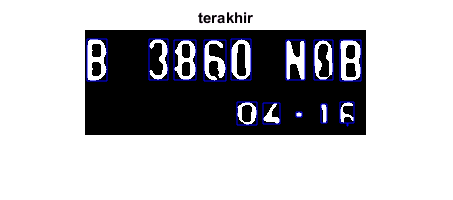

T = graythresh(segmented_images{idx(2)});
tes = imbinarize(segmented_images{idx(2)}, T);
se = strel('rectangle',[3,3]);
erosi = imerode(tes,se);
hasil_akhir = imclearborder(erosi, 4);
hasil_akhir = medfilt2(hasil_akhir, [4 4]);
hasil_akhir = bwmorph(hasil_akhir, 'bridge', 8);
bb = regionprops(hasil_akhir,'BoundingBox');
figure;
imshow(hasil_akhir),
title('terakhir');
hold on ; %tetap mengaktifan figur citra biner di atas

for i=1:size(bb,1)
    s = bb(i)
    %menggambar kotak BoundingBox setiap objek
    rectangle('Position', bb(i).BoundingBox,'edgecolor','blue');
end

Tampilkan PerKarakter

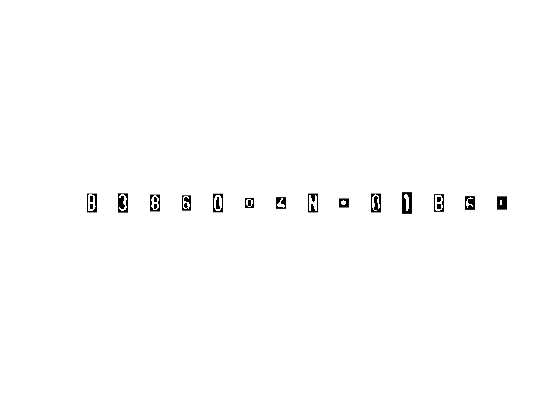

L=bwlabel(hasil_akhir,8);
siz=size(hasil_akhir);
n=max(L(:)); % number of objects
ObjCell=cell(n,1);
for i=1:n
      % Get the bb of the i-th object and offest by 2 pixels in all
      % directions
      bb_i=ceil(bb(i).BoundingBox);
      idx_x=[bb_i(1)-2 bb_i(1)+bb_i(3)+2];
      idx_y=[bb_i(2)-2 bb_i(2)+bb_i(4)+2];
      if idx_x(1)<1, idx_x(1)=1; end
      if idx_y(1)<1, idx_y(1)=1; end
      if idx_x(2)>siz(2), idx_x(2)=siz(2); end
      if idx_y(2)>siz(1), idx_y(2)=siz(1); end
      % Crop the object and write to ObjCell
      im=L==i;
      ObjCell{i}=im(idx_y(1):idx_y(2),idx_x(1):idx_x(2));
end
% Visualize the individual objects
figure
for i=1:n
    subplot(1,n,i)
    imshow(ObjCell{i})
end